% clear all;
% close all
warn = warning ('off','all');

% range, startpoint and target
Xmin=-25;           %range of image
Ymin=-25;
Xmax=25;
Ymax=25;
start_point=[-20 ; 0]; % start point of all nodes
var=10;% point generate variance
wt=[20 ; 0]; % target point location

% coefficients
N=150;      % no. of nodes
dt=0.5;     % time increment / time step
times=50; %Number of iterations
R=3.5;   % neighborhood radius
r=3; % node distance limit
r_min=3;% minimum tolerant distance
d=2; % distance of population from the walls (red)
d_high=7; % distance of population from the walls (green)
chord_threshold=34; % wall width (chord length) change threshold 
x_chord_begin=40;
x_chord_end=120;
tail_l=0.5;
dmax=1;

%velocity parameters
lamda=0.5;  
alpha=2;
alpha_max=3;
beta=2;
gamma=2; 
mu=0.5;

% define wall models
cor_width=4;
% syms P1(z) P2(z)
% P1(z)= 0.003*(z-70)^2 +25;
% P2(z)= -0.003*(z-100)^2 +10;
% Pd1=diff(P1);% derivative of wall equations
% Pd2=diff(P2);
steps1=500;
steps2=500;
z1=linspace(cor_width/2,Ymax,steps1).';
z2=linspace(-cor_width/2,Ymin,steps2).';
% yP1=P1(z1);
% yP2=P2(z2);
xz1=zeros(steps1,1);
xz2=zeros(steps2,1);
curvexy1=[xz1 z1];
curvexy2=[xz2 z2];


% boundaries of wall
xz_limit_r=xz1-d;
xz_limit_g=xz1-d_high;
curvexy_limit1=[xz_limit_r z1];
curvexy_limit2=[xz_limit_r z2];
curvexy_limit3=[xz_limit_g z1];
curvexy_limit4=[xz_limit_g z2];

x_fill_r=[xz1.', fliplr(xz_limit_r.')];
x_fill_g=[xz_limit_r.', fliplr(xz_limit_g.')];
y_fill_1 = [z1.', fliplr(z1.')];
y_fill_2 = [z2.', fliplr(z2.')];



% directing 
interval=30;
steps_direct=linspace(start_point(1),wt(1),interval).';% x
% directx=[steps_direct(2:end-1)];
% midpoint=double((P1(directx)+P2(directx))/2); % y
% directxy=[directx.'; midpoint.'];
% directxy=[directxy,wt];
directxy=[steps_direct.';zeros(1,interval)];
% directxy=wt;
directx=directxy(1,:);
directy=directxy(2,:);


% block
% circle_cent=[230 35];
% circle_r=10;

% performance test
test_times=1;
fish_go_out=zeros(times,test_times);
for test_t = 1 : test_times

    % generating the initial population (distributed in acircle with radius 'var')
    x=zeros(2,N,times+1); % location of all nodes (uniformly distribute in a circle with radius var)
    rng(test_t);
    radius = var*sqrt(rand(1,N)); % Using square root here ensures distribution uniformity by area
    rng(test_t+1);
    t = 2*pi*rand(1,N);
    x_cor = radius.*cos(t);
    y_cor = radius.*sin(t);
    x(:,:,1)=[start_point(1)+x_cor;start_point(2)+y_cor];
    x(:,:,2)=[start_point(1)+x_cor;start_point(2)+y_cor];
    
    % define all variables
    u=zeros(2,N,times+1); % velocity of all nodes
    ua=zeros(2,N,times+1); % heading target velocity of all nodes
    ub=zeros(2,N,times+1);% reunion velocity
    uc=zeros(2,N,times+1); % coherent motion velocity
    delta=zeros(2,N,times+1);
    ug=zeros(2,N,times); % gravity center velocity
    dist=zeros(N,times); % distance from each node to target
    phi=zeros(2,N,times+1);
    flag_edge=zeros(N,times);
    chord_length=zeros(N,times);
    chord_centre=zeros(2,N,times);
    r_change=r*ones(N,times);
    alpha_change=alpha*ones(N,times+1);
    targetxy=zeros(2,N,times);
    dist_nodek_alltime=zeros(N,N,times);
    vind_all_include=cell(N);
    tailxy=zeros(2,N,times+1);
    u_should=zeros(2,N,times+1);% the original u before replaced
    % initialize velocity 
    u(:,:,2)=(wt-x(:,:,1))./vecnorm(wt-x(:,:,1));
    % initialize tail 
    tailxy(:,:,1)=x(:,:,1);
    
    % at time t, location is updated by u(:,k,t+1)
    for t=2:times
        max_all_x=max(x(1,:,t));
        tind=find(directx>max_all_x | directx==directx(end),1);% find the next directing point 
        targetxy(:,:,t)=repmat(directxy(:,tind),1,N);
        dist(:,t)=vecnorm(targetxy(:,:,t)-x(:,:,t)).'; % dist between each node and target
        dist_nodek=zeros(N,N); % distance between every two nodes (l,k)
        
        
        % distance from node to the closer wall
        pointsxy=x(:,:,t).';
        [xy1,distances1,~] = distance2curve(curvexy1,pointsxy,'linear');
        [xy2,distances2,~] = distance2curve(curvexy2,pointsxy,'linear');
        wallpoints1=xy1.';
        wallpoints2=xy2.';
    
        for k=1:N
            % update neighbourhood
            dist_nodek(:,k)=vecnorm(x(:,:,t)-x(:,k,t)).'; % distance between k and its neighbour
            dist_nodek_alltime(:,k,t)=dist_nodek(:,k);
            vind=find(dist_nodek(:,k)<=R & dist_nodek(:,k)>0); % index of neighbourhood (doesn't include itself)
            vind_all_include{k}=find(dist_nodek(:,k)<=R); % index of  neighbourhood (include itself)
            vind_nonneigh=find(dist_nodek(:,k)>R);% index of outside neighbourhood 
            Nk=length(vind_all_include{k}); % number of neighbours of k
    
            % decide subtarget (closest neighbour)
            if  (distances1(k)<=d_high || distances2(k)<=d_high) && x(1,k,t) < 0 && distances1(k)>d
                lowestd=Inf;
                subtarget=-1;
                for nid = vind.' % search every neighbour 
                    if dist(k,t) > dmax * dist(nid,t)
                        if dist_nodek(nid,k) < lowestd
                            lowestd = dist_nodek(nid,k);
                            subtarget=nid;
                        end
                    end
                end
            end

            % update heading target velocity / avoid collision velocity
                ua_raw=[];
                if distances1(k)<=d_high && distances1(k)<distances2(k) && x(1,k,t) < 0
                    if distances1(k)>d && subtarget ~= -1 % out of red and has subtarget
                        ua_raw=[ua_raw (x(:,subtarget,t)-x(:,k,t))./dist_nodek(subtarget,k)];
                        ua_raw=[ua_raw (targetxy(:,k,t)-x(:,k,t))/dist(k,t)];
                        ua(:,k,t+1) = mean(ua_raw,2)/norm(mean(ua_raw,2)); % prevent ua to small
                    elseif distances1(k)>d && subtarget == -1
                        ua(:,k,t+1)=(targetxy(:,k,t)-x(:,k,t))/dist(k,t);
                    elseif distances1(k)<=d % no subtarget (has to avoid obstacle)
                        ua_raw=[ua_raw (d/distances1(k)-1)*(x(:,k,t)-wallpoints1(:,k))];
                        ua_raw=[ua_raw (targetxy(:,k,t)-x(:,k,t))/dist(k,t)];
                        ua(:,k,t+1)=mean(ua_raw,2)/norm(mean(ua_raw,2)); % prevent ua to small
                    end
                elseif distances2(k)<=d_high && distances2(k)<distances1(k) && x(1,k,t) < 0
                    if distances2(k)>d && subtarget ~= -1 % out of red and has subtarget
                        ua_raw=[ua_raw (x(:,subtarget,t)-x(:,k,t))./dist_nodek(subtarget,k)];
                        ua_raw=[ua_raw (targetxy(:,k,t)-x(:,k,t))/dist(k,t)];
                        ua(:,k,t+1) = mean(ua_raw,2)/norm(mean(ua_raw,2)); % prevent ua to small
                    elseif distances2(k)>d && subtarget == -1
                        ua(:,k,t+1)=(targetxy(:,k,t)-x(:,k,t))/dist(k,t);
                    elseif distances2(k)<=d % no subtarget (has to avoid obstacle)
                        ua_raw=[ua_raw (d/distances2(k)-1)*(x(:,k,t)-wallpoints2(:,k))];
                        ua_raw=[ua_raw (targetxy(:,k,t)-x(:,k,t))/dist(k,t)];
                        ua(:,k,t+1)=mean(ua_raw,2)/norm(mean(ua_raw,2)); % prevent ua to small
                    end
                else % no obstacle in sight
                    ua(:,k,t+1)=(targetxy(:,k,t)-x(:,k,t))/dist(k,t);
                end
    
            % update gravity center velocity
            ug(:,k,t)=mean(phi(:,vind_all_include{k},t),2);
    
            % reunion 
            % decide which edge
            W=[u(1,k,t)/norm(u(:,k,t)) -u(2,k,t)/norm(u(:,k,t)); u(2,k,t)/norm(u(:,k,t)) u(1,k,t)/norm(u(1,k,t))]; 
            xlk=zeros(2,N);
            for l=vind  % just care about neighbor fish
                xlk(:,l)=W'*(x(:,l,t)-x(:,k,t)); % (W times every relative location of fish k)
            end
            if xlk(1,:)==-abs(xlk(1,:)) % (all negative, no node l lies in the front of k) k is at front
               flag_edge(k,t)=1;
            elseif xlk(2,:)==abs(xlk(2,:)) % (all positive, all nodes l lie in left of node k) l(s) are all at left, k is at right edge
               flag_edge(k,t)=2;
            elseif xlk(2,:)==-abs(xlk(2,:)) % l(s) are all at right, k is at left edge
               flag_edge(k,t)=3;
            else 
               flag_edge(k,t)=0;
            end
           
            % update coherent motion velocity (avoid collisions)
            if Nk > 1
                delta(:,k,t)=(1/(Nk-1)) * sum((1-r_change(k,t)./dist_nodek(vind,k)).' .*  (x(:,vind,t)-x(:,k,t)),2); % 重合
            end
            uc(:,k,t+1)=(1-lamda)*ug(:,k,t)+gamma*delta(:,k,t);
    
           
            % update velocity of each node 
            u(:,k,t+1)=lamda*(alpha_change(k,t+1).*ua(:,k,t+1)+beta*ub(:,k,t))+uc(:,k,t+1);
    
            
    
            % update location
            x(:,k,t+1)=x(:,k,t)+dt*u(:,k,t+1);

            y_atwall=(x(2,k,t+1)-x(2,k,t))/(x(1,k,t+1)-x(1,k,t))*abs(x(1,k,t+1)-x(1,k,t))+x(2,k,t);
            % dont go out
            if x(1,k,t+1) > 0 && x(1,k,t) < 0 && y_atwall >= cor_width/2
                x(:,k,t+1)=x(:,k,t);
                u_should(:,k,t+1)=u(:,k,t+1);
                u(:,k,t+1)=[0;0];
            end
            if x(1,k,t+1) > 0 && x(1,k,t) < 0 && y_atwall <= -cor_width/2
                x(:,k,t+1)=x(:,k,t);
                u_should(:,k,t+1)=u(:,k,t+1);
                u(:,k,t+1)=[0;0];
            end
            if x(1,k,t) > 0 && x(1,k,t+1) <= 0
                x(:,k,t+1)=x(:,k,t);
                u_should(:,k,t+1)=u(:,k,t+1);
                u(:,k,t+1)=[0;0];
            end
            

            % count go out fish
            fish_go_out(t,test_t)=length(find(x(1,:,t)>0));

            % update phi (local center of gravity velocity elements)
            phi(:,k,t+1)=(1-mu)*ug(:,k,t)+mu*u(:,k,t+1);  
        end
    
        % tail generation
        % unit velocity
        u_mag=repmat(vecnorm(u(:,:,t+1)),2,1);
        u_unit=u(:,:,t+1)./u_mag;
        % tail point
        tailxy(:,:,t)=x(:,:,t)-tail_l*u_unit;
    
        % set reunion velocity
        % find the nearest edge (different from itself)
        for k=1:N
            flag_out_neigh=flag_edge(:,t);
            flag_out_neigh(vind_all_include{k})=0;% flag for nodes outside the neighbour of node k
            if flag_edge(k,t)==1 % front
               tb =find(flag_out_neigh == 1); % the index of same edges
               if length(tb) == 0
                   ub(:,k,t+1)=zeros(2,1);
               else
                   dist_kl=dist_nodek(tb,k);    
                   [~, ind]= min(dist_kl);
                   l=tb(ind);
                   ub(:,k,t+1)= (x(:,l,t) - x(:,k,t))/norm(x(:,l,t) - x(:,k,t));
               end
           
            elseif flag_edge(k,t)==2 % right
               tb =find(flag_out_neigh == 2); % the index of same edges
               if length(tb) == 0
                   ub(:,k,t+1)=zeros(2,1);
               else
                   dist_kl=dist_nodek(tb,k);    
                   [~, ind]= min(dist_kl);
                   l=tb(ind);
                   ub(:,k,t+1)= (x(:,l,t) - x(:,k,t))/norm(x(:,l,t) - x(:,k,t));
               end
    
            elseif flag_edge(k,t)==3 % left
               tb =find(flag_out_neigh == 3); % the index of same edges
               if length(tb) == 0
                   ub(:,k,t+1)=zeros(2,1);
               else
                   dist_kl=dist_nodek(tb,k);    
                   [~, ind]= min(dist_kl);
                   l=tb(ind);
                   ub(:,k,t+1)= (x(:,l,t) - x(:,k,t))/norm(x(:,l,t) - x(:,k,t));
               end
            else 
                ub(:,k,t+1)=zeros(2,1);
            end
        end 
    end
    
    % gennerate tail matrix
    tail_draw=zeros(2,3*N,times);
    for t=1:times
        for k=1:N
            tail_draw(:,3*(k-1)+1,t)=x(:,k,t);
            tail_draw(:,3*(k-1)+2,t)=tailxy(:,k,t);
            tail_draw(:,3*(k-1)+3,t)=[NaN;NaN];
        end
    end
    Xtail=squeeze(tail_draw(1,:,:));
    Ytail=squeeze(tail_draw(2,:,:));
end

% % plot video
% for t = 2 : times
%     figure('Visible', 'off');
%     hold on;
%     % walls
%     plot(curvexy1(:,1),curvexy1(:,2),'k.','MarkerSize',2)
%     plot(curvexy2(:,1),curvexy2(:,2),'k.','MarkerSize',2)
%     % wall boundary 
%     plot(curvexy_limit1(:,1),curvexy_limit1(:,2),'r.','MarkerSize',2)
%     plot(curvexy_limit2(:,1),curvexy_limit2(:,2),'r.','MarkerSize',2)
%     plot(curvexy_limit1(:,1),curvexy_limit1(:,2),'g.','MarkerSize',2)
%     plot(curvexy_limit2(:,1),curvexy_limit2(:,2),'g.','MarkerSize',2)
% %     % block
% %     circle(circle_cent(1),circle_cent(2),circle_r);
%     % nodes
%     scatter(x(1,:,t),x(2,:,t),'.','b');
%     % target(guide)
%     scatter(targetxy(1,1,t),targetxy(2,1,t),'.','r')
%     % tail
%     plot(Xtail(:,t), Ytail(:,t), '-b');
%     % start and end points
%     scatter(wt(1),wt(2),'*','r');
%     scatter(start_point(1),start_point(2),'*','black')
%     % axis (xy limit)
%     axis([Xmin Xmax+20 Ymin Ymax]);
%     axis equal
%     hold off;
%     
%     drawnow
%     ax = gca;
%     ax.Units = 'pixels';
%     pos = ax.Position;
%     marg = 30;
%     rect = [-marg, -marg, pos(3)+2*marg, pos(4)+2*marg];
%     M(t-1) = getframe(gca,rect);
%     ax.Units = 'normalized';
% end
% 
% myVideo = VideoWriter('green_red.avi');
% open(myVideo);
% writeVideo(myVideo, M);
% close(myVideo);

t = 2

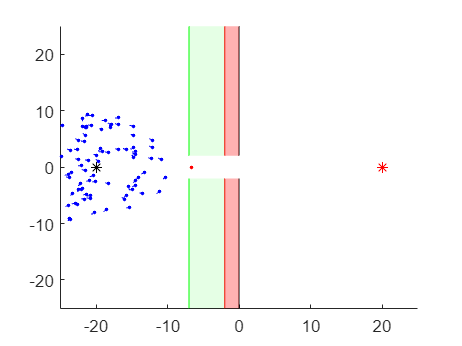

t = 4

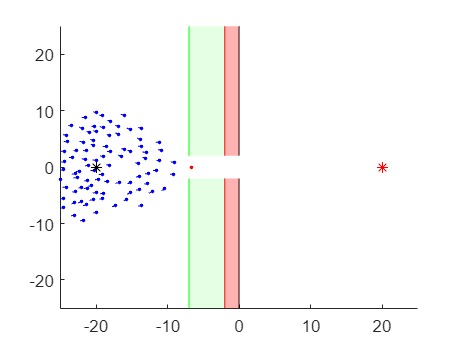

t = 6

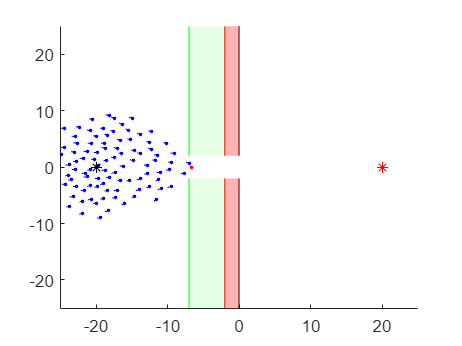

t = 8

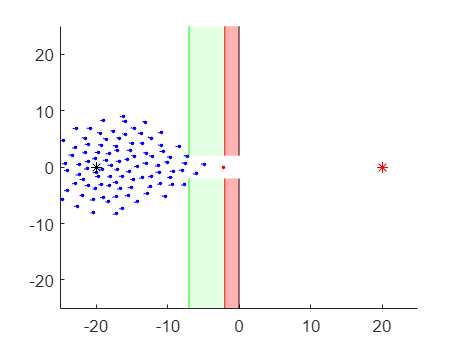

t = 10

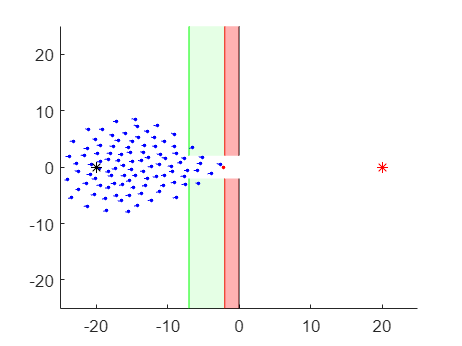

t = 12

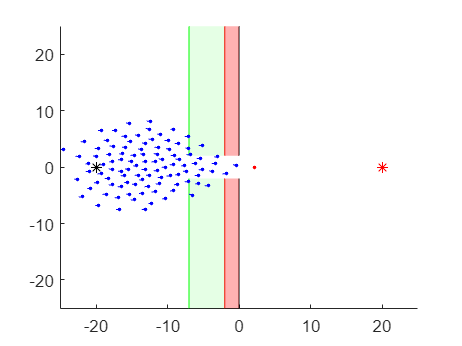

t = 14

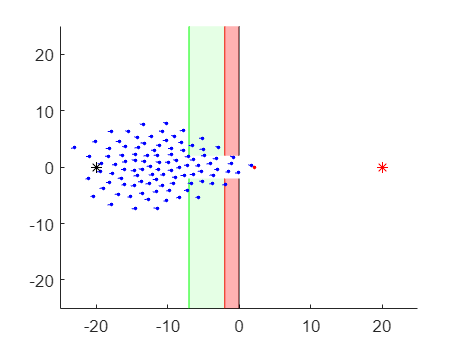

t = 16

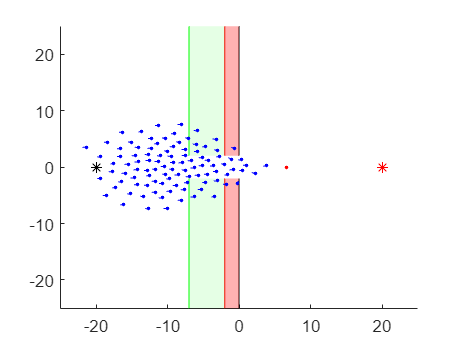

t = 18

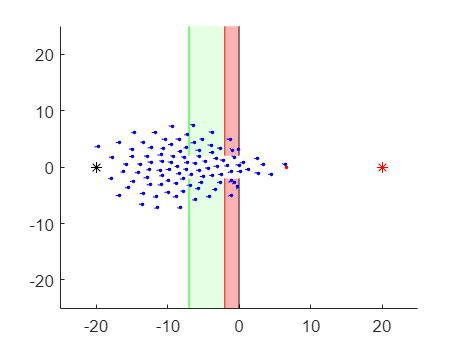

t = 20

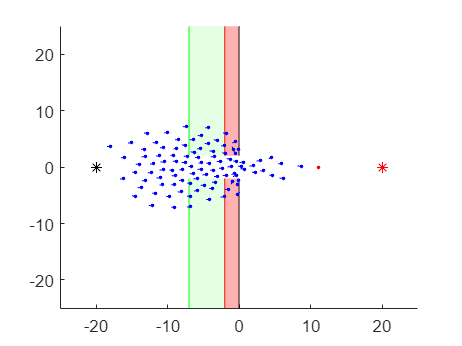

t = 22

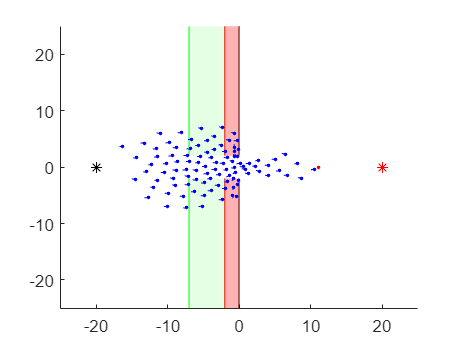

t = 24

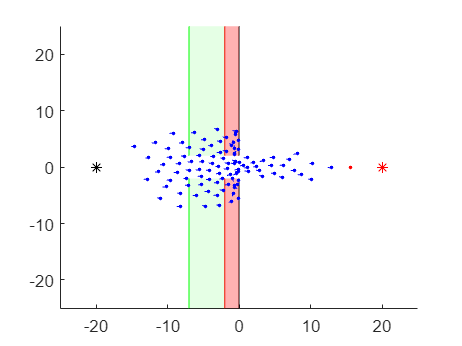

t = 26

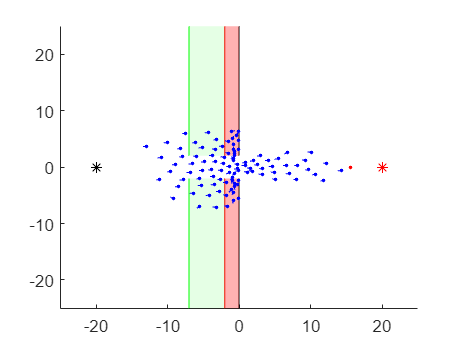

t = 28

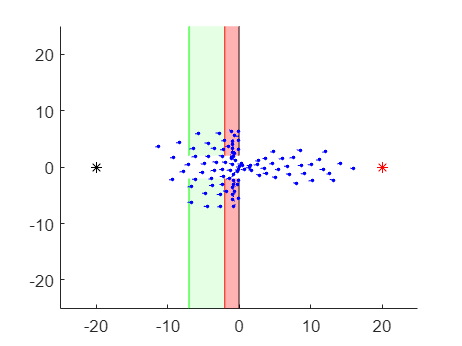

t = 30

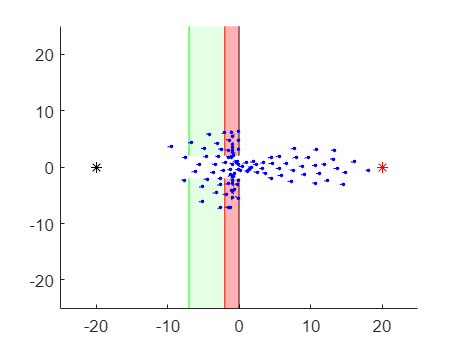

t = 32

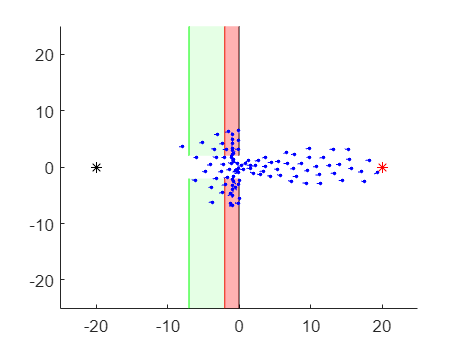

t = 34

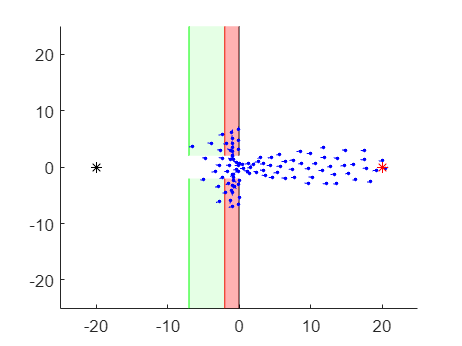

t = 36

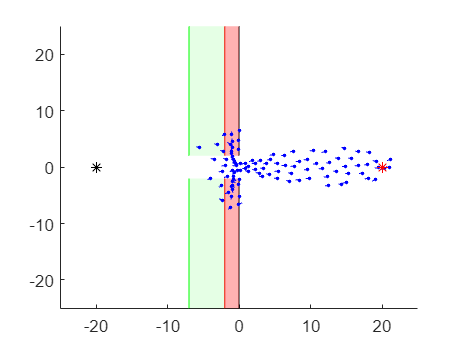

t = 38

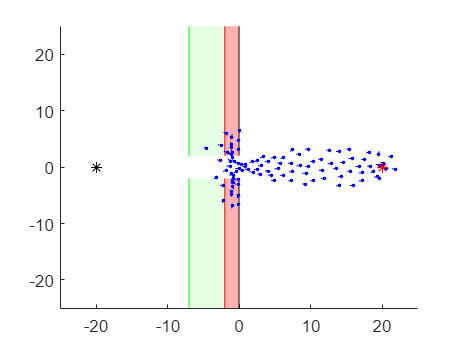

t = 40

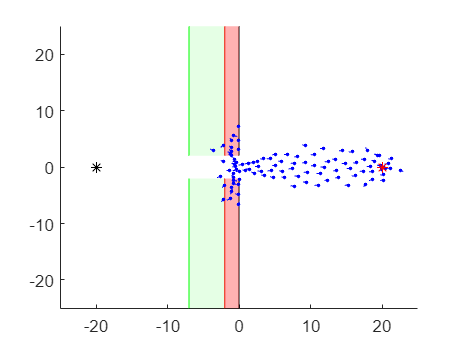

t = 42

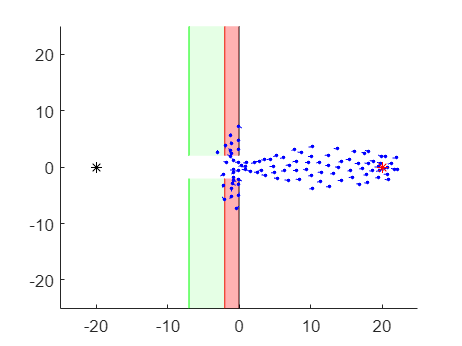

t = 44

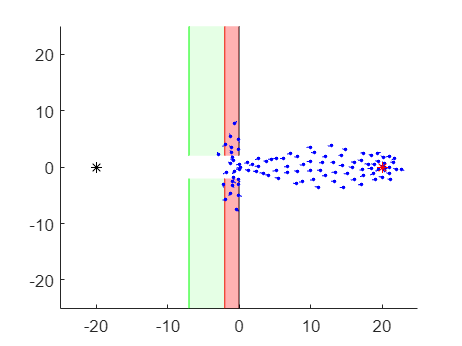

t = 46

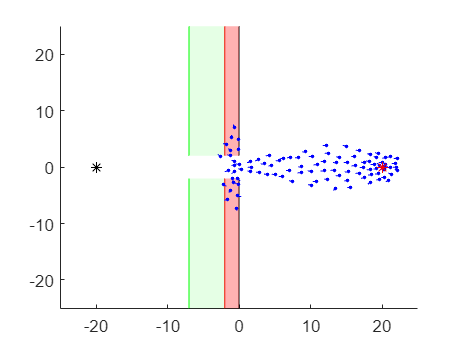

t = 48

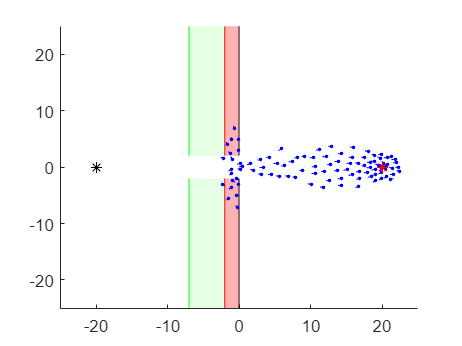

t = 50

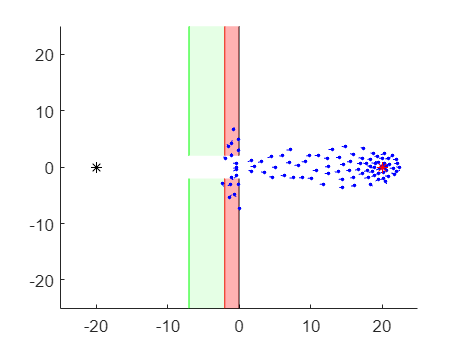

t = 52

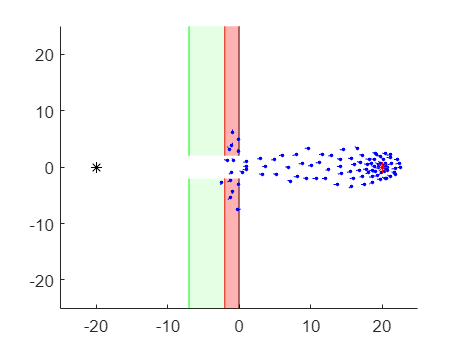

t = 54

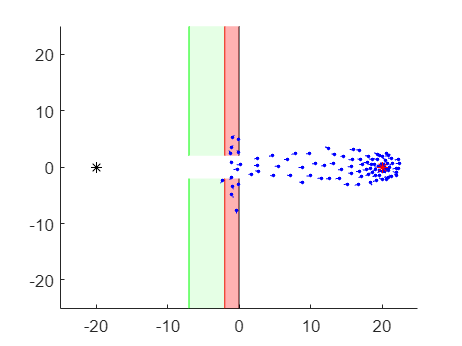

t = 56

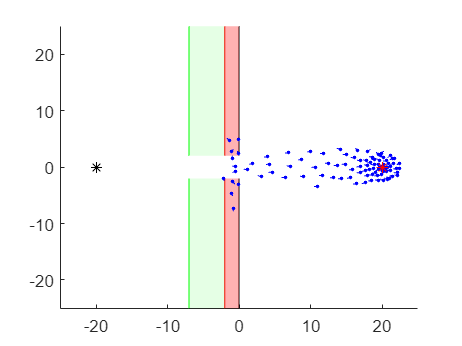

t = 58

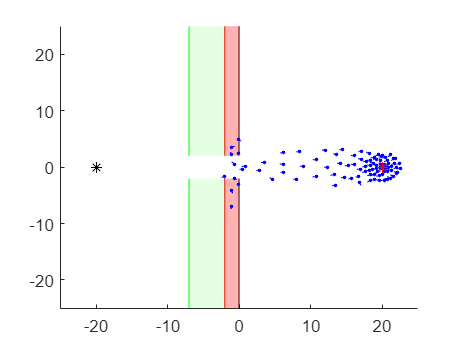

t = 60

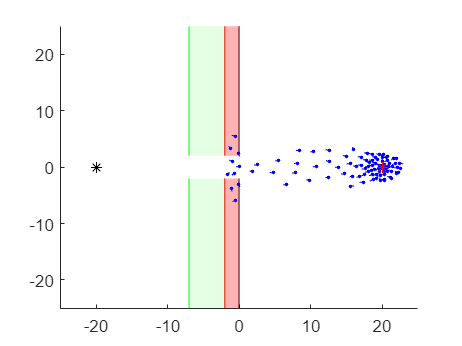

t = 62

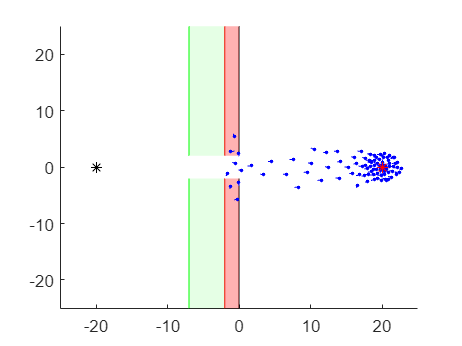

t = 64

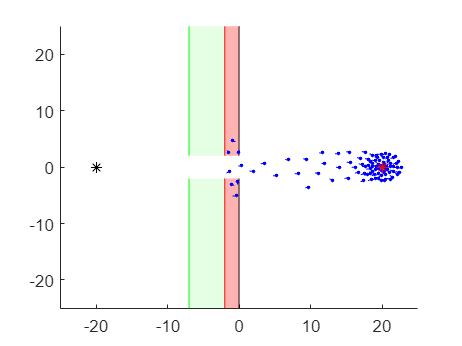

t = 66

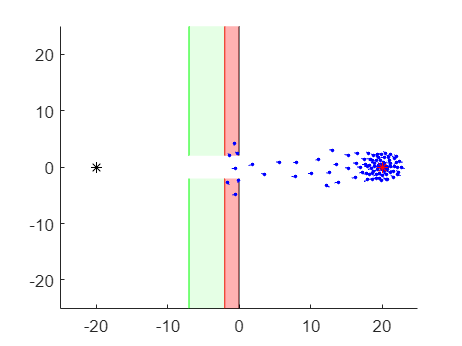

t = 68

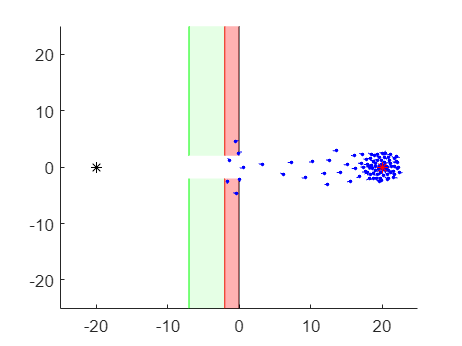

t = 70

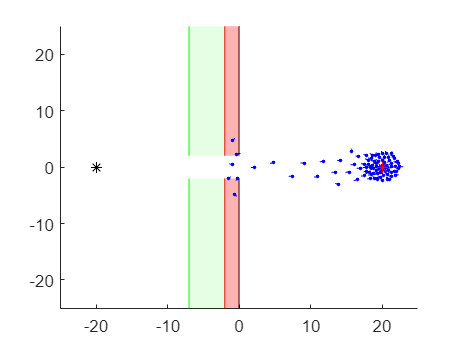

t = 72

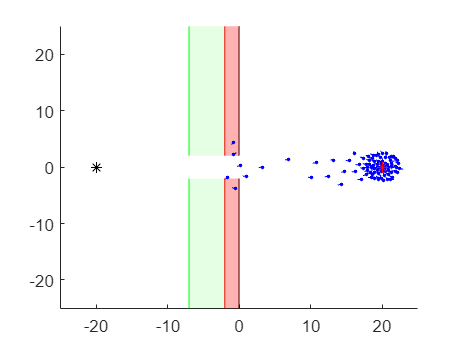

t = 74

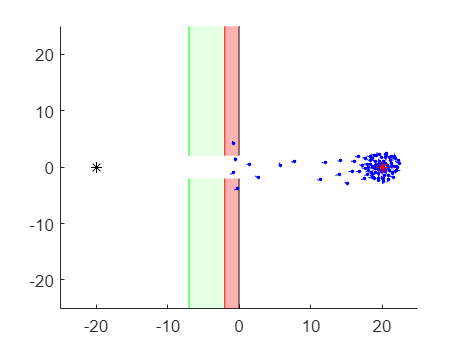

t = 76

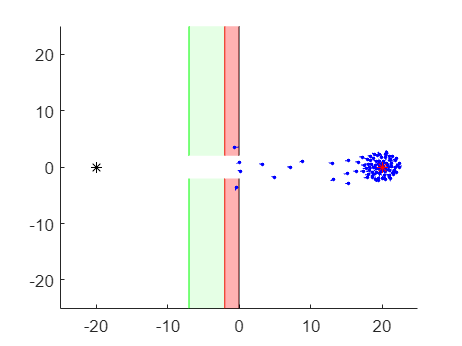

t = 78

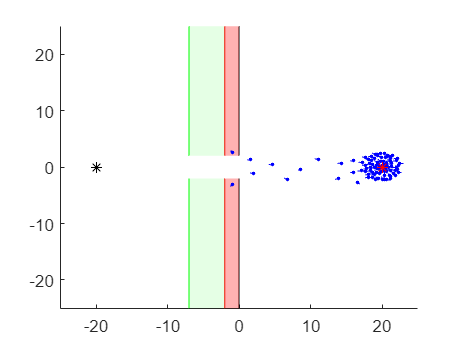

t = 80

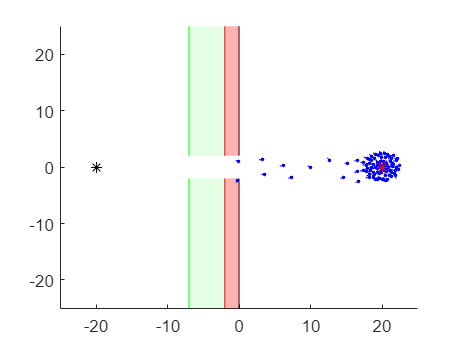

t = 82

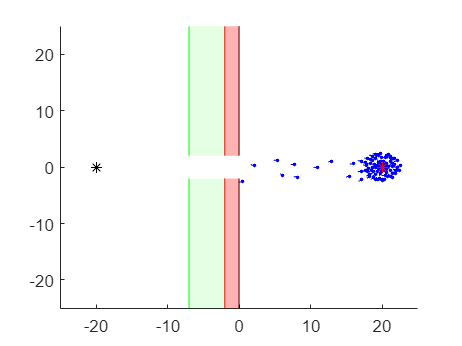

t = 84

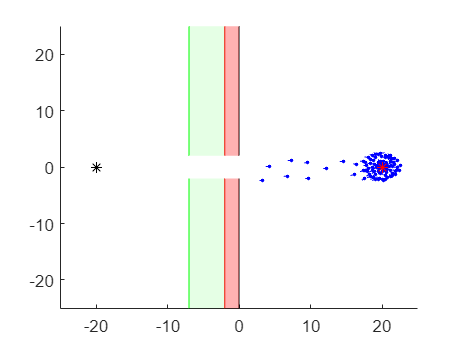

t = 86

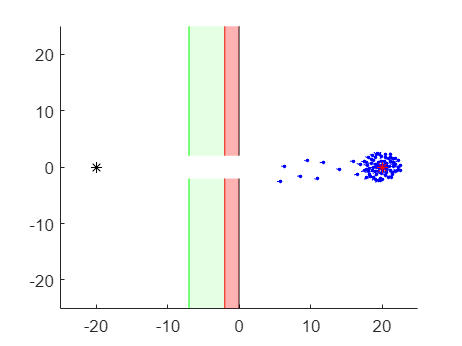

t = 88

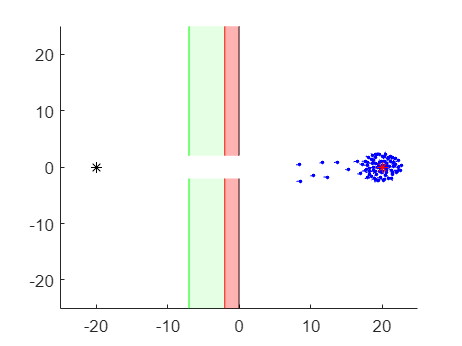

t = 90

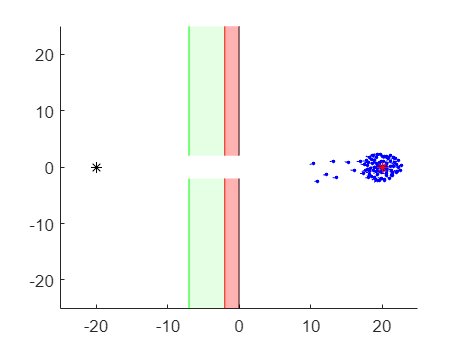

t = 92

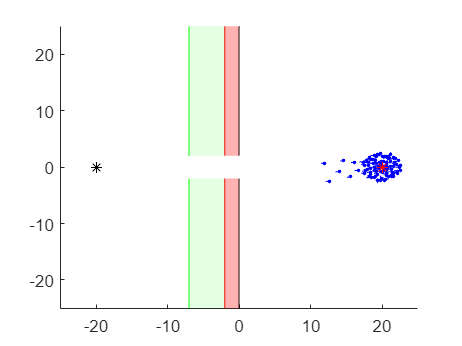

t = 94

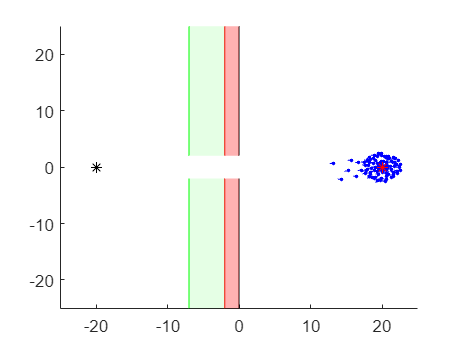

t = 96

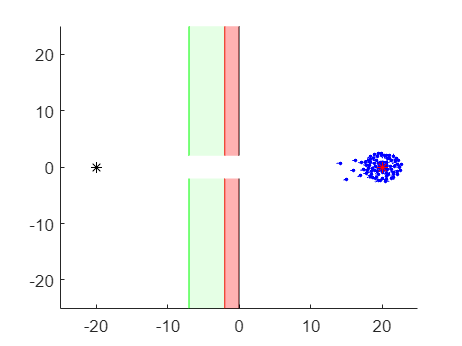

t = 98

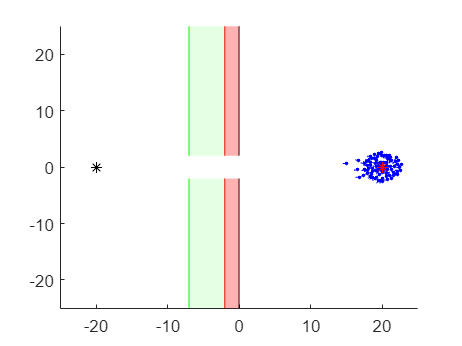

t = 100

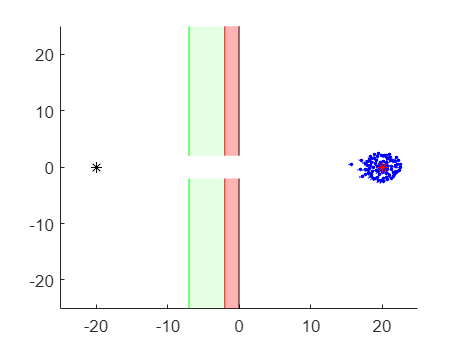

% plot figures
for t = 2:2:times
    t
    figure;
    hold on;
    % walls
    plot(curvexy1(:,1),curvexy1(:,2),'k','MarkerSize',2)
    plot(curvexy2(:,1),curvexy2(:,2),'k','MarkerSize',2)
    % wall boundary 
    plot(curvexy_limit1(:,1),curvexy_limit1(:,2),'r','MarkerSize',2)
    plot(curvexy_limit2(:,1),curvexy_limit2(:,2),'r','MarkerSize',2)
    plot(curvexy_limit3(:,1),curvexy_limit3(:,2),'g','MarkerSize',2)
    plot(curvexy_limit4(:,1),curvexy_limit4(:,2),'g','MarkerSize',2)
    % fill
    fill(x_fill_r, y_fill_1, 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    fill(x_fill_r, y_fill_2, 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    fill(x_fill_g, y_fill_1, 'g', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
    fill(x_fill_g, y_fill_2, 'g', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
    % nodes
    scatter(x(1,:,t),x(2,:,t),'.','b');
    % target(guide)
    scatter(targetxy(1,1,t),targetxy(2,1,t),'.','r')
    % tail
    plot(Xtail(:,t), Ytail(:,t), '-b');
    % start and end points
    scatter(wt(1),wt(2),'*','r');
    scatter(start_point(1),start_point(2),'*','black')
    % axis (xy limit)
    axis([Xmin Xmax Ymin Ymax]);

%     axis equal
    hold off;

%     zp=BaseZoom();
%     zp.plot;
end   

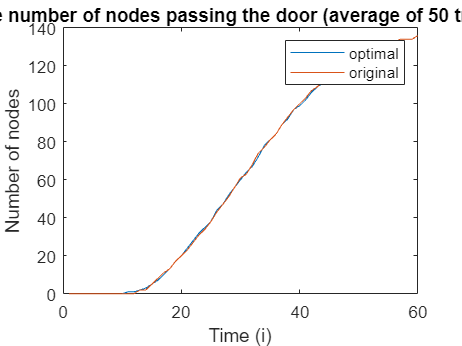

% plot test 
mean_test=mean(fish_go_out,2);
mean_test2=mean(fish_go_out2,2);
figure;
plot(mean_test);
hold on;
plot(mean_test2);
legend('optimal','original');
xlabel('Time (i)')
ylabel('Number of nodes')
title('The number of nodes passing the door (average of 50 trials).')

function h = circle(x,y,r)
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit,'MarkerSize',2);
end